%     Data Science (Prof. Neff)                Versuchsdatum 21.11.2020
%     Versuch Konfidenzintervalle
%     Gruppe 6:    Benjamin Hamm (2060696), Jan Klotter (2060690),
%     Anna Kuhn (2051063), Michael Schulze (2061282)
%     
%     Rohdaten der einzelnen Gruppenmitglieder


% Aufgabe 1
%Büroklammern
data_buero = readtable('Lebensdauer_Bueroklammer.csv')

data_buero = 75×1 table
    Zyklen
    ______

       9  
      61  
       3  
       2  
       4  
       7  
      25  
      16  
      97  
       4  
       5  
      50  
       2  
       2  
      13  
      17  



% Bueroklammern b)
mean_norm = mean(data_buero.Zyklen)

mean_norm = 15.6133

pd_norm_buero = fitdist(data_buero.Zyklen,'Normal')

pd_norm_buero =   NormalDistribution

  Normal distribution
       mu = 15.6133   [10.6343, 20.5924]
    sigma = 21.6407   [18.6461, 25.7903]


ci_normal=paramci(pd_norm_buero,'Alpha',0.05)

ci_normal =    10.6343   18.6461
   20.5924   25.7903



[h0,p,t_ci_buero,t_stats_buero] = ttest(data_buero.Zyklen)

h0 = 1

p = 2.3904e-08

t_ci_buero =    10.6343
   20.5924


t_stats_buero = struct with fields:
    tstat: 6.2482
       df: 74
       sd: 21.6407



pd_wybul_buero = fitdist(data_buero.Zyklen, 'Weibull')

pd_wybul_buero =   WeibullDistribution

  Weibull distribution
    A =  15.2792   [11.8995, 19.6187]
    B = 0.960767   [0.820185, 1.12545]


ci_weibull = paramci(pd_wybul_buero,'Alpha',0.05)

ci_weibull =    11.8995    0.8202
   19.6187    1.1254



pd = makedist('Weibull')

pd =   WeibullDistribution

  Weibull distribution
    A = 1
    B = 1


qqplot(data_buero.Zyklen,pd)
%bis 2,8 eindeutige Weibull-Verteilung, danach sind Outliner vorhanden.
%daher nehmen wir die Weibull-Verteilung als gute Näherung einer
%Verteilung an

[boot_buero, data_boot_buero]=bootstrp(10,@median,data_buero.Zyklen)

boot_buero =      9
    11
    12
    12
     9
     9
    11
     9
    11
    11


data_boot_buero =      6    34    69    16    65    13     5    46    29    74
    36    17    23    11    29     5     5    34    69     8
    67    50    51    14    48    40    49    50    66     6
    33    47    13    12    67    26    19    49    28    74
    59    43    73    13    58    41    55    51    10    57
    45    42    25    68    70    40    41     7    24    21
    24     9    22    33    10    55    36    32    18    55
    74    34    47    11    11    18    31    16    46    11
    57    60     7     1    37    73    14    38    49    23
    68    11    41     8    38    49    63    39    55    63


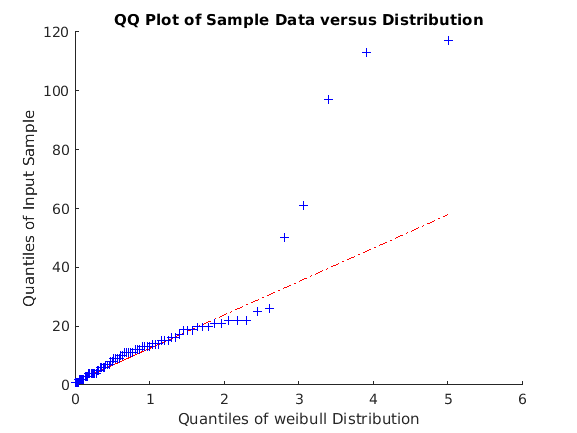


figure(2)

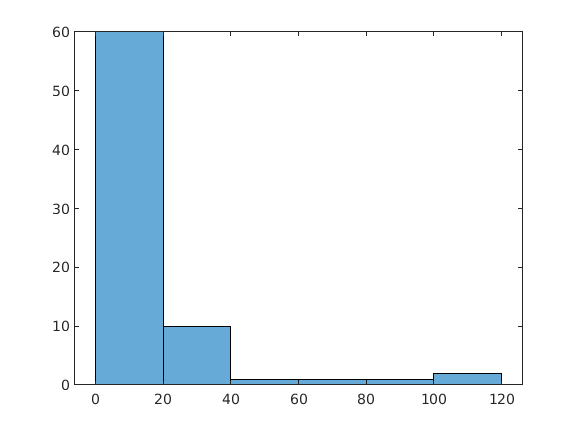

histogram(data_buero.Zyklen)

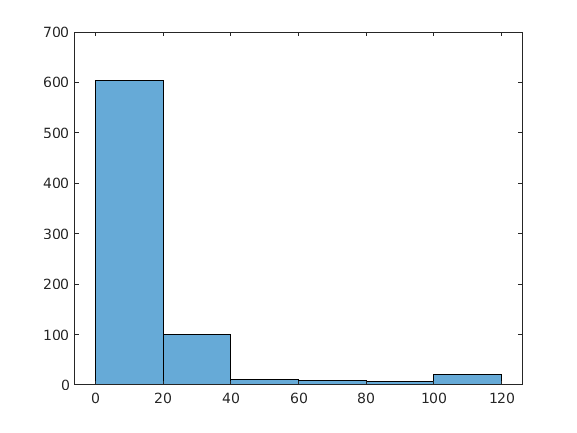


histogram(data_buero.Zyklen(data_boot_buero),6)


[ci,mean_intervall_bootstrap] = bootci(10,{@mean,data_buero.Zyklen},'Alpha',0.05)

ci =    13.6400
   22.4133


mean_intervall_bootstrap =    18.8000
   14.4667
   19.3867
   16.7733
   14.9467
   17.2533
   13.6400
   22.4133
   13.8533
   17.5467


%Bootstrap vergrößert künstlich die Stichprobe, daher ist das
%Konvidenzintervall kleiner als bei den anderen Verfahren,
%daher nehmen wir das Bootstrap-Verfahren ebenfalls als geeignet an

matrix = [mean_norm ci_normal(1) ci_normal(2);
    mean_norm t_ci_buero(1) t_ci_buero(2);
    mean_norm ci_weibull(1) ci_weibull(2);
    mean(mean_intervall_bootstrap) ci(1) ci(2)]

matrix =    15.6133   10.6343   20.5924
   15.6133   10.6343   20.5924
   15.6133   11.8995   19.6187
   16.9080   13.6400   22.4133


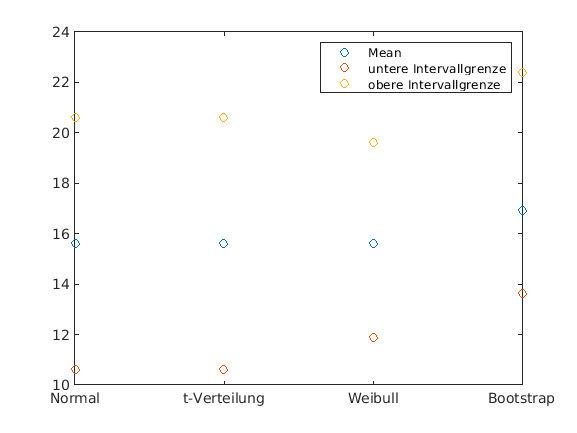

plot(matrix,'o')
legend( "Mean", "untere Intervallgrenze", "obere Intervallgrenze")
xlim([1 4])
xticks([1 2 3 4])
xticklabels({'Normal', 't-Verteilung', 'Weibull', 'Bootstrap'})

%Bootstrap und Weibull eignen sich am besten, da die Konvidenzintervall am
%kleinsten sind (im Gegensatz zur Normal- und t-Verteilung).
%Der qqPlot der Weibull ist annähern linear bis 2,8



% Wasser MSA1 b)
data_msa = readtable('MSA_Verfahren1_200ml_Jan.csv')

data_msa = 25×1 table
    Gewicht_in_g
    ____________

        199     
        213     
        185     
        198     
        205     
        191     
        184     
        193     
        199     
        206     
        207     
        210     
        213     
        197     
        205     
        203     



mean_norm = mean(data_msa.Gewicht_in_g)

mean_norm = 200.0400


pd = makedist('Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 0
    sigma = 1


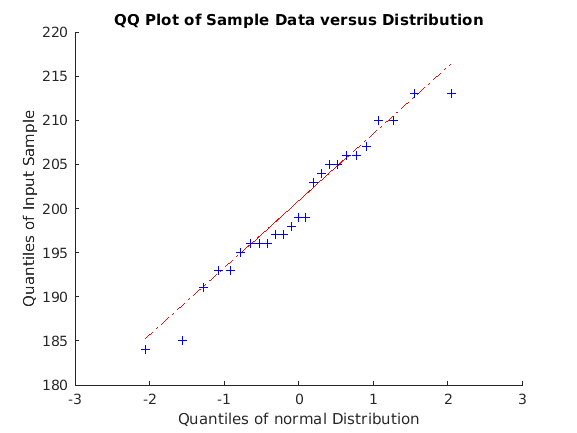

qqplot(data_msa.Gewicht_in_g,pd)

%qqPlot der Normalverteilung nähert sich den Daten am genausten an

pd_norm_msa = fitdist(data_msa.Gewicht_in_g, 'Normal')

pd_norm_msa =   NormalDistribution

  Normal distribution
       mu =  200.04   [196.787, 203.293]
    sigma = 7.88184   [6.15436, 10.9648]


ci_normal_msa = paramci(pd_norm_msa, 'Alpha', 0.05)

ci_normal_msa =   196.7865    6.1544
  203.2935   10.9648



[~,~,t_ci_msa,t_stats_msa] = ttest(data_msa.Gewicht_in_g)

t_ci_msa =   196.7865
  203.2935


t_stats_msa = struct with fields:
    tstat: 126.8994
       df: 24
       sd: 7.8818



pd_wybul_msa = fitdist(data_msa.Gewicht_in_g,'Weibull')

pd_wybul_msa =   WeibullDistribution

  Weibull distribution
    A =  203.71   [200.821, 206.64]
    B = 29.0413   [21.4884, 39.2491]


ci_wybul_msa = paramci(pd_wybul_msa, 'Alpha', 0.05)

ci_wybul_msa =   200.8207   21.4884
  206.6400   39.2491



[boot_msa, data_boot_msa]=bootstrp(10,@median,data_msa.Gewicht_in_g)

boot_msa =    203
   198
   205
   203
   197
   205
   197
   198
   199
   199


data_boot_msa =     10     7    21    16     6    16    16     3    10     1
     3     3     1    23    12    12     5    10     5    17
    25    12    17     3    15    12    25    16    13     4
     3     7    12    10    10     8    18     4    24    18
    12    23    15    21    25    25    20     1    24    20
    18     4    13    18     2    17     3    22    11     2
    11     6     3     2     3     4    14    22     3    24
     2     6    11    19     5    13     3     8    25     4
    18    12    13    17    19    12    11    10    18     5
    18    11     2     2     6    12    23    18    18    13


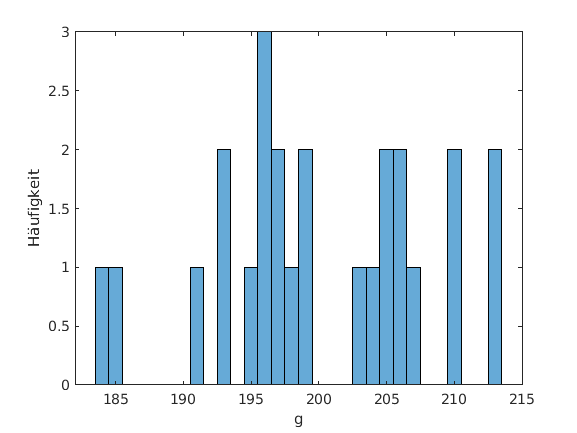



histogram(data_msa.Gewicht_in_g)
xlabel("g")
ylabel("Häufigkeit")

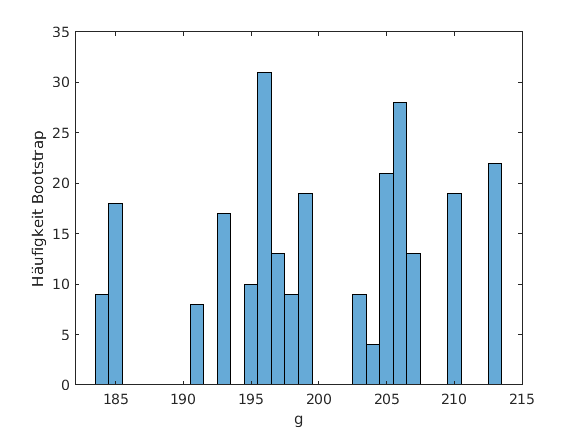

histogram(data_msa.Gewicht_in_g(data_boot_msa))
xlabel("g")
ylabel("Häufigkeit Bootstrap")


[ci,mean_intervall_bootstrap] = bootci(10,{@mean,data_msa.Gewicht_in_g},'Alpha',0.05)

ci =   197.5379
  201.4800


mean_intervall_bootstrap =   199.2800
  200.1200
  197.0800
  200.6800
  199.8000
  199.9200
  201.4800
  200.0000
  199.9600
  200.6400


pd = makedist('Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 0
    sigma = 1


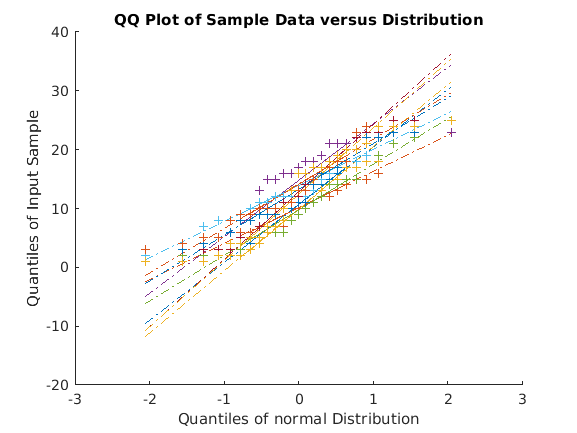

qqplot(data_boot_msa,pd)


matrix = [mean_norm ci_normal_msa(1) ci_normal_msa(2);
    mean_norm t_ci_msa(1) t_ci_msa(2);
    mean_norm ci_wybul_msa(1) ci_wybul_msa(2);
    mean(mean_intervall_bootstrap) ci(1) ci(2)]

matrix =   200.0400  196.7865  203.2935
  200.0400  196.7865  203.2935
  200.0400  200.8207  206.6400
  199.8960  197.5379  201.4800


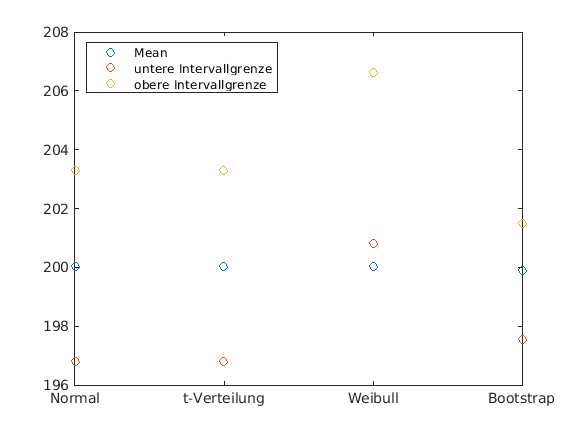

plot(matrix,'o')
legend( "Mean", "untere Intervallgrenze", "obere Intervallgrenze", 'Location', 'northwest')
xlim([1 4])
xticks([1 2 3 4])
xticklabels({'Normal', 't-Verteilung', 'Weibull', 'Bootstrap'})

%die Normal und t-Verteilung zeigen gute Näherungen für die Daten
%das Bootstrap Verfahren hat jedoch ein kleineres Konfidenzintervall und
%ist somit noch besser geeignet als die anderen beiden.
%Weibull kann nicht angewandt werden, der Mittelwert liegt sogar außerhalb
%des Konfidenzintervalls

% Aufgabe 2
% Medikament hat keine Auswirkung auf Cholesterin
data_cholesterin_senker = readtable('cholesterinsenker.csv')

data_cholesterin_senker = 10×2 table
     A      B 
    ___    ___

      0    -22
    -27    -14
    -16    -15
    -13    -32
     -6    -22
    -27    -34
     -5    -38
    -22    -16
     -9    -25
     -3    -26


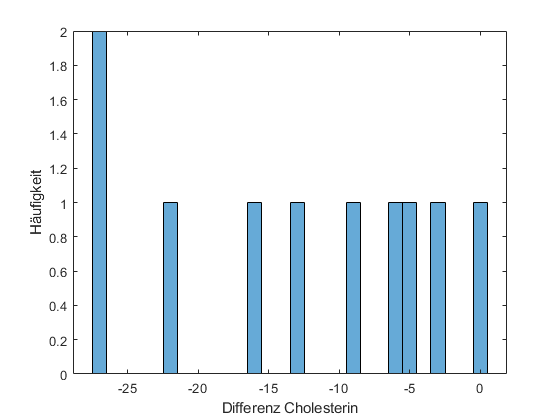


histogram(data_cholesterin_senker.A)
xlabel("Differenz Cholesterin")
ylabel("Häufigkeit")

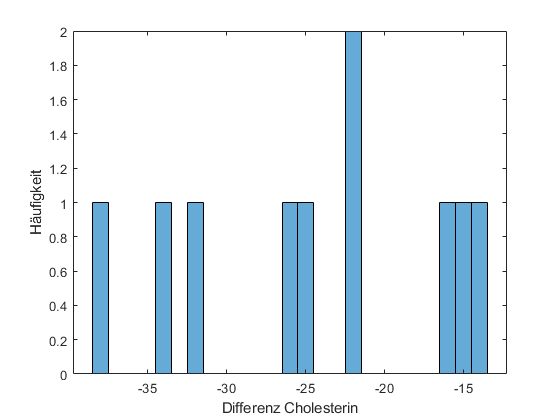


histogram(data_cholesterin_senker.B)
xlabel("Differenz Cholesterin")
ylabel("Häufigkeit")

%t-Test
data_cholesterin_senker = readtable('cholesterinsenker.csv')

data_cholesterin_senker = 10×2 table
     A      B 
    ___    ___

      0    -22
    -27    -14
    -16    -15
    -13    -32
     -6    -22
    -27    -34
     -5    -38
    -22    -16
     -9    -25
     -3    -26


fprintf("A erster Parameter")

A erster Parameter

[h0_ttest,p_ttest,ci_ttest,stats_ttest]=ttest2(data_cholesterin_senker.A,data_cholesterin_senker.B, 'alpha',0.01)

h0_ttest = 0

p_ttest = 0.0107

ci_ttest =    -0.1355
   23.3355


stats_ttest = struct with fields:
    tstat: 2.8452
       df: 18
       sd: 9.1165


%1: h0 ablehnen, 0: h0 nicht ablehnen = beibehalten

%verteilungsfreien Test auf Median:
[h0_rank,p_rank,stats_rank]=ranksum(data_cholesterin_senker.A,data_cholesterin_senker.B, 'alpha',0.01)

h0_rank = 0.0280

p_rank = logical
   0


stats_rank = struct with fields:
       zval: 2.1972
    ranksum: 134.5000


% 2e) Anderson_Darling_Test
[h0_adA, p_adA, ci_adA, stats_adA] = adtest(data_cholesterin_senker.A,'Alpha',0.01)

h0_adA = logical
   0


p_adA = 0.4677

ci_adA = 0.3289

stats_adA = 0.9339

[h0_adB, p_adB, ci_adB, stats_adB] = adtest(data_cholesterin_senker.B,'Alpha',0.01)

h0_adB = logical
   0


p_adB = 0.6616

ci_adB = 0.2635

stats_adB = 0.9339


%Verteilungsunabhängige Konfidenzintervalle für Quantile
%Berechnung des Konfidenzintervalls für den Median (McGill 1978)
% ci_lower=median()-1.57*(quantile(data,0.75)-quantile(data,0.25))/sqrt(anzahl)
% ci_upper=median(data)+1.57*(quantile(data,0.75)-quantile(data,0.25))/sqrt(anzahl)
% ci_median=[ci_lower,ci_upper]

%Veranschaulichung der Verteilung incl. Konfidenzintervall vom Median im
%Boxplot (Matlab verwendet obige Formel)
pd = makedist('Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 0
    sigma = 1


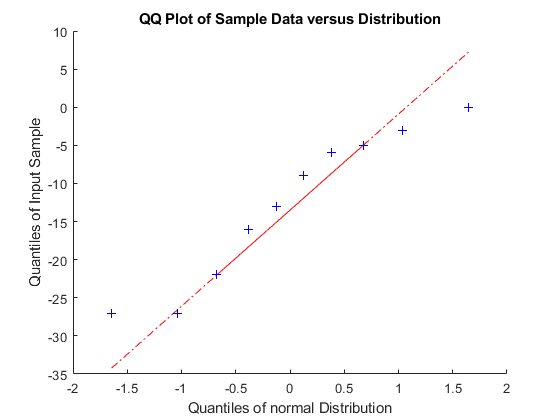

qqplot(data_cholesterin_senker.A,pd)

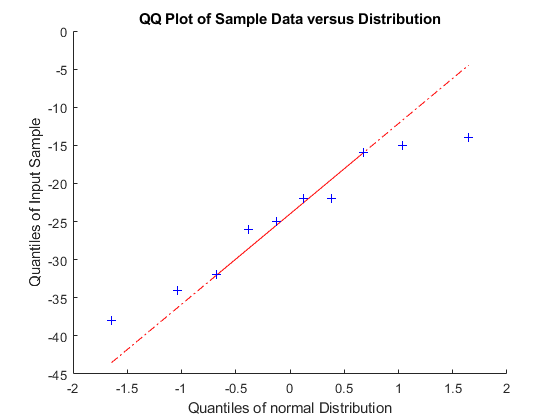

qqplot(data_cholesterin_senker.B,pd)